%% ANÁLISIS DEL ATRACTOR DE LÜ - CORRECCIÓN CASOS DEGENERADOS
% Sistema:
% x' = α(y - x)
% y' = -xz + δy  
% z' = xy - βz

clear; clc; close all;

%% PARÁMETROS Y CONFIGURACIÓN
alpha = 36;
beta = 3;
delta = 20;

% Condiciones iniciales
initial_conditions = [0.1, 0.3, -0.6];

%% 8.1 - PUNTOS CRÍTICOS EN FUNCIÓN DE PARÁMETROS
fprintf('=== 8.1 - PUNTOS CRÍTICOS ===\n');

=== 8.1 - PUNTOS CRÍTICOS ===



% Definir sistema simbólico
syms x y z a b d
f1 = a*(y - x);
f2 = -x*z + d*y;
f3 = x*y - b*z;

% Resolver sistema para puntos críticos
[x_sol, y_sol, z_sol] = solve(f1 == 0, f2 == 0, f3 == 0, x, y, z);

fprintf('Puntos críticos encontrados:\n');

Puntos críticos encontrados:


for i = 1:length(x_sol)
    fprintf('P%d = (%s, %s, %s)\n', i, char(x_sol(i)), char(y_sol(i)), char(z_sol(i)));
end

P1 = (0, 0, 0)
P2 = (-(b*d)^(1/2), -(b*d)^(1/2), d)
P3 = ((b*d)^(1/2), (b*d)^(1/2), d)



% Evaluar con parámetros específicos
x_crit = subs(x_sol, [a, b, d], [alpha, beta, delta]);
y_crit = subs(y_sol, [a, b, d], [alpha, beta, delta]);
z_crit = subs(z_sol, [a, b, d], [alpha, beta, delta]);

fprintf('\nPuntos críticos con α=%g, β=%g, δ=%g:\n', alpha, beta, delta);


Puntos críticos con α=36, β=3, δ=20:


for i = 1:length(x_crit)
    fprintf('P%d = (%.4f, %.4f, %.4f)\n', i, double(x_crit(i)), double(y_crit(i)), double(z_crit(i)));
end

P1 = (0.0000, 0.0000, 0.0000)
P2 = (-7.7460, -7.7460, 20.0000)
P3 = (7.7460, 7.7460, 20.0000)



%% 8.2 - ESTABILIDAD DEL ORIGEN (0,0,0) - CASOS COMPLETOS CORREGIDOS
fprintf('\n=== 8.2 - ESTABILIDAD DEL ORIGEN - ANÁLISIS COMPLETO ===\n');


=== 8.2 - ESTABILIDAD DEL ORIGEN - ANÁLISIS COMPLETO ===



% Matriz jacobiana
J = jacobian([f1; f2; f3], [x, y, z]);

% ================================================
% CASO 1: Todos los parámetros distintos de 0
% ================================================
fprintf('\n--- CASO 1: α≠0, β≠0, δ≠0 ---\n');


--- CASO 1: α≠0, β≠0, δ≠0 ---



J_origin_1 = subs(J, [x, y, z], [0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_1);

$$\left(\begin{array}{ccc} -a & a & 0\\ 0 & d & 0\\ 0 & 0 & -b \end{array}\right)$$


% Evaluar con parámetros específicos
J_origin_1_num = double(subs(J_origin_1, [a, b, d], [alpha, beta, delta]));
eigenvals_1_num = eig(J_origin_1_num);

fprintf('Autovalores numéricos con α=%g, β=%g, δ=%g:\n', alpha, beta, delta);

Autovalores numéricos con α=36, β=3, δ=20:


for i = 1:length(eigenvals_1_num)
    fprintf('λ%d = %.4f %+.4fi\n', i, real(eigenvals_1_num(i)), imag(eigenvals_1_num(i)));
end

λ1 = -36.0000 +0.0000i
λ2 = 20.0000 +0.0000i
λ3 = -3.0000 +0.0000i



% Determinar estabilidad
if all(real(eigenvals_1_num) < 0)
    fprintf('ESTABLE: todos los autovalores tienen parte real negativa\n');
elseif all(real(eigenvals_1_num) <= 0)
    fprintf('MARGINALMENTE ESTABLE\n');
else
    fprintf('INESTABLE: al menos un autovalor tiene parte real positiva\n');
end

INESTABLE: al menos un autovalor tiene parte real positiva



% ================================================
% CASO 2: Todos los parámetros iguales a 0 - CORREGIDO
% ================================================
fprintf('\n--- CASO 2: α=0, β=0, δ=0 ---\n');


--- CASO 2: α=0, β=0, δ=0 ---



J_origin_2 = subs(J, [x, y, z, a, b, d], [0, 0, 0, 0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_2);

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


det_J_2 = det(J_origin_2);
fprintf('Determinante: %s\n', char(det_J_2));

Determinante: 0



eigenvals_2 = eig(J_origin_2);
fprintf('Autovalores:\n');

Autovalores:


for i = 1:length(eigenvals_2)
    fprintf('λ%d = %s\n', i, char(eigenvals_2(i)));
end

λ1 = 0
λ2 = 0
λ3 = 0



fprintf('ANÁLISIS: Todos los autovalores son cero\n');

ANÁLISIS: Todos los autovalores son cero


fprintf('SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA\n');

SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA



% ================================================
% CASO 3: α=δ=0 y β≠0 - CORREGIDO
% ================================================
fprintf('\n--- CASO 3: α=0, δ=0, β≠0 ---\n');


--- CASO 3: α=0, δ=0, β≠0 ---



% Sustituir completamente en la matriz jacobiana
J_origin_3 = subs(J, [x, y, z, a, d], [0, 0, 0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_3);

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & -b \end{array}\right)$$


det_J_3 = det(J_origin_3);
fprintf('Determinante: %s\n', char(det_J_3));

Determinante: 0



eigenvals_3 = eig(J_origin_3);
fprintf('Autovalores:\n');

Autovalores:


for i = 1:length(eigenvals_3)
    fprintf('λ%d = %s\n', i, char(simplify(eigenvals_3(i))));
end

λ1 = 0
λ2 = 0
λ3 = -b



% Evaluar numéricamente con β específico
beta_test = 3;
J_origin_3_num = double(subs(J_origin_3, b, beta_test));
eigenvals_3_num = eig(J_origin_3_num);

fprintf('\nAutovalores numéricos con β=%g:\n', beta_test);


Autovalores numéricos con β=3:


for i = 1:length(eigenvals_3_num)
    fprintf('λ%d = %.4f %+.4fi\n', i, real(eigenvals_3_num(i)), imag(eigenvals_3_num(i)));
end

λ1 = -3.0000 +0.0000i
λ2 = 0.0000 +0.0000i
λ3 = 0.0000 +0.0000i



fprintf('ANÁLISIS: Autovalor real negativo (-β) y autovalor cero doble\n');

ANÁLISIS: Autovalor real negativo (-β) y autovalor cero doble


fprintf('SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA\n');

SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA



% ================================================
% CASO 4: α=0 y δ≠0 (β arbitrario) - CORREGIDO
% ================================================
fprintf('\n--- CASO 4: α=0, δ≠0 (β arbitrario) ---\n');


--- CASO 4: α=0, δ≠0 (β arbitrario) ---



J_origin_4 = subs(J, [x, y, z, a], [0, 0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_4);

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & d & 0\\ 0 & 0 & -b \end{array}\right)$$


% Evaluar con parámetros específicos
delta_test = 20;
beta_test = 3;
J_origin_4_num = double(subs(J_origin_4, [b, d], [beta_test, delta_test]));
eigenvals_4_num = eig(J_origin_4_num);

fprintf('Autovalores numéricos con δ=%g, β=%g:\n', delta_test, beta_test);

Autovalores numéricos con δ=20, β=3:


for i = 1:length(eigenvals_4_num)
    fprintf('λ%d = %.4f %+.4fi\n', i, real(eigenvals_4_num(i)), imag(eigenvals_4_num(i)));
end

λ1 = -3.0000 +0.0000i
λ2 = 0.0000 +0.0000i
λ3 = 20.0000 +0.0000i



% Determinar estabilidad
if all(real(eigenvals_4_num) < 0)
    fprintf('ESTABLE: todos los autovalores tienen parte real negativa\n');
elseif all(real(eigenvals_4_num) <= 0)
    fprintf('MARGINALMENTE ESTABLE\n');
else
    fprintf('INESTABLE: al menos un autovalor tiene parte real positiva\n');
end

INESTABLE: al menos un autovalor tiene parte real positiva



% ================================================
% CASO 5: α≠0 y β=0 (δ arbitrario) - CORREGIDO
% ================================================
fprintf('\n--- CASO 5: α≠0, β=0 (δ arbitrario) ---\n');


--- CASO 5: α≠0, β=0 (δ arbitrario) ---



J_origin_5 = subs(J, [x, y, z, b], [0, 0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_5);

$$\left(\begin{array}{ccc} -a & a & 0\\ 0 & d & 0\\ 0 & 0 & 0 \end{array}\right)$$


% Evaluar con parámetros específicos
alpha_test = 36;
delta_test = 20;
J_origin_5_num = double(subs(J_origin_5, [a, d], [alpha_test, delta_test]));
eigenvals_5_num = eig(J_origin_5_num);

fprintf('Autovalores numéricos con α=%g, δ=%g:\n', alpha_test, delta_test);

Autovalores numéricos con α=36, δ=20:


for i = 1:length(eigenvals_5_num)
    fprintf('λ%d = %.4f %+.4fi\n', i, real(eigenvals_5_num(i)), imag(eigenvals_5_num(i)));
end

λ1 = -36.0000 +0.0000i
λ2 = 20.0000 +0.0000i
λ3 = 0.0000 +0.0000i



fprintf('ANÁLISIS: Determinante cero → sistema singular\n');

ANÁLISIS: Determinante cero → sistema singular


fprintf('SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA\n');

SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA



% ================================================
% CASO 6: α≠0 y β≠0 (δ arbitrario) - CORREGIDO
% ================================================
fprintf('\n--- CASO 6: α≠0, β≠0 (δ arbitrario) ---\n');


--- CASO 6: α≠0, β≠0 (δ arbitrario) ---



J_origin_6 = subs(J, [x, y, z], [0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_6);

$$\left(\begin{array}{ccc} -a & a & 0\\ 0 & d & 0\\ 0 & 0 & -b \end{array}\right)$$


% Evaluar con δ específico
delta_test = 20;
J_origin_6_num = double(subs(J_origin_6, [a, b, d], [alpha, beta, delta_test]));
eigenvals_6_num = eig(J_origin_6_num);

fprintf('Autovalores numéricos con α=%g, β=%g, δ=%g:\n', alpha, beta, delta_test);

Autovalores numéricos con α=36, β=3, δ=20:


for i = 1:length(eigenvals_6_num)
    fprintf('λ%d = %.4f %+.4fi\n', i, real(eigenvals_6_num(i)), imag(eigenvals_6_num(i)));
end

λ1 = -36.0000 +0.0000i
λ2 = 20.0000 +0.0000i
λ3 = -3.0000 +0.0000i



% Determinar estabilidad
if all(real(eigenvals_6_num) < 0)
    fprintf('ESTABLE: todos los autovalores tienen parte real negativa\n');
elseif all(real(eigenvals_6_num) <= 0)
    fprintf('MARGINALMENTE ESTABLE\n');
else
    fprintf('INESTABLE: al menos un autovalor tiene parte real positiva\n');
end

INESTABLE: al menos un autovalor tiene parte real positiva



%% GRÁFICAS DE TRAYECTORIAS PARA TODOS LOS CASOS
fprintf('\n=== GRÁFICAS DE TRAYECTORIAS PARA TODOS LOS CASOS ===\n');


=== GRÁFICAS DE TRAYECTORIAS PARA TODOS LOS CASOS ===



% Condiciones iniciales múltiples para ver comportamiento
initial_conditions_set = [
    0.1, 0.3, -0.6;
    1.0, 0.5, 0.2;
    -0.5, -0.8, 0.4;
    0.01, 0.01, 0.01
];

% Colores para diferentes condiciones iniciales
colors = ['r', 'g', 'b', 'm'];

%% CASO 1: α≠0, β≠0, δ≠0 (Caso normal - Atractor de Lü)
fprintf('\nGraficando CASO 1 (α≠0, β≠0, δ≠0)...\n');


Graficando CASO 1 (α≠0, β≠0, δ≠0)...


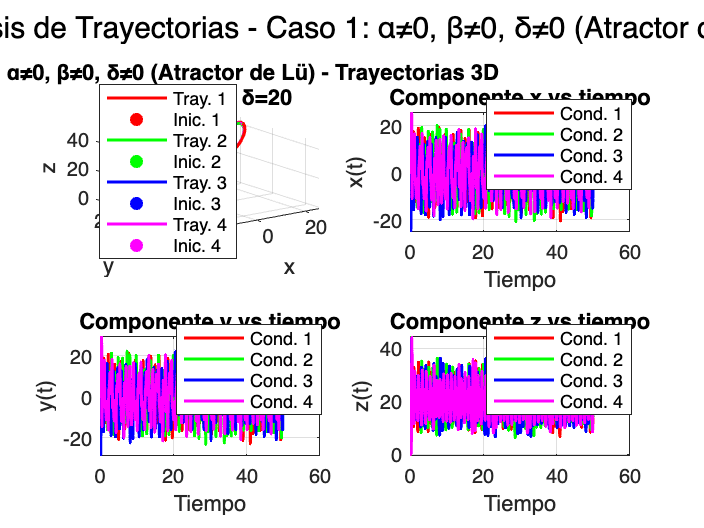


alpha_val = 36;
beta_val = 3;
delta_val = 20;
case_name = 'Caso 1: α≠0, β≠0, δ≠0 (Atractor de Lü)';
t_span = [0, 50];

% Definir el sistema de ecuaciones
lorenz_system = @(t, X) [
    alpha_val * (X(2) - X(1));
    -X(1)*X(3) + delta_val * X(2);
    X(1)*X(2) - beta_val * X(3)
];

figure('Position', [100, 100, 1200, 900]);

for i = 1:size(initial_conditions_set, 1)
    try
        % Resolver el sistema
        [t, X] = ode45(lorenz_system, t_span, initial_conditions_set(i, :));
        
        % Gráfica 3D
        subplot(2, 2, 1);
        plot3(X(:,1), X(:,2), X(:,3), colors(i), 'LineWidth', 1.5);
        hold on;
        plot3(X(1,1), X(1,2), X(1,3), [colors(i) 'o'], 'MarkerSize', 6, 'MarkerFaceColor', colors(i));
        
        % Gráficas de componentes vs tiempo
        subplot(2, 2, 2);
        plot(t, X(:,1), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 3);
        plot(t, X(:,2), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 4);
        plot(t, X(:,3), colors(i), 'LineWidth', 1.5); hold on;
    catch ME
        fprintf('Advertencia: No se pudo resolver para condición inicial %d\n', i);
    end
end

% Configurar gráfica 3D
subplot(2, 2, 1);
grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title(sprintf('%s - Trayectorias 3D\nα=%g, β=%g, δ=%g', case_name, alpha_val, beta_val, delta_val));
legend('Tray. 1', 'Inic. 1', 'Tray. 2', 'Inic. 2', 'Tray. 3', 'Inic. 3', 'Tray. 4', 'Inic. 4', 'Location', 'best');

% Configurar gráficas de componentes
subplot(2, 2, 2);
grid on; xlabel('Tiempo'); ylabel('x(t)');
title('Componente x vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 3);
grid on; xlabel('Tiempo'); ylabel('y(t)');
title('Componente y vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 4);
grid on; xlabel('Tiempo'); ylabel('z(t)');
title('Componente z vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

sgtitle(sprintf('Análisis de Trayectorias - %s', case_name));


%% CASO 2: α=β=δ=0 (Completamente degenerado)
fprintf('\nGraficando CASO 2 (α=β=δ=0)...\n');


Graficando CASO 2 (α=β=δ=0)...


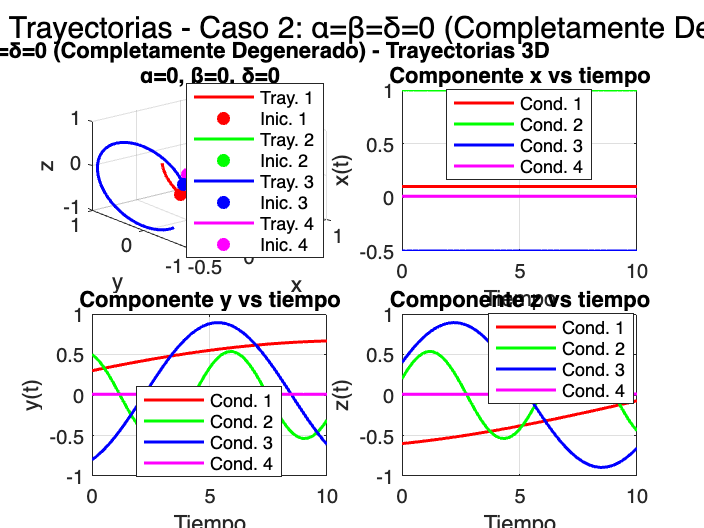


alpha_val = 0;
beta_val = 0;
delta_val = 0;
case_name = 'Caso 2: α=β=δ=0 (Completamente Degenerado)';
t_span = [0, 10];

% Definir el sistema de ecuaciones
lorenz_system = @(t, X) [
    alpha_val * (X(2) - X(1));
    -X(1)*X(3) + delta_val * X(2);
    X(1)*X(2) - beta_val * X(3)
];

figure('Position', [100, 100, 1200, 900]);

for i = 1:size(initial_conditions_set, 1)
    try
        % Resolver el sistema
        [t, X] = ode45(lorenz_system, t_span, initial_conditions_set(i, :));
        
        % Gráfica 3D
        subplot(2, 2, 1);
        plot3(X(:,1), X(:,2), X(:,3), colors(i), 'LineWidth', 1.5);
        hold on;
        plot3(X(1,1), X(1,2), X(1,3), [colors(i) 'o'], 'MarkerSize', 6, 'MarkerFaceColor', colors(i));
        
        % Gráficas de componentes vs tiempo
        subplot(2, 2, 2);
        plot(t, X(:,1), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 3);
        plot(t, X(:,2), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 4);
        plot(t, X(:,3), colors(i), 'LineWidth', 1.5); hold on;
    catch ME
        fprintf('Advertencia: No se pudo resolver para condición inicial %d\n', i);
    end
end

% Configurar gráfica 3D
subplot(2, 2, 1);
grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title(sprintf('%s - Trayectorias 3D\nα=%g, β=%g, δ=%g', case_name, alpha_val, beta_val, delta_val));
legend('Tray. 1', 'Inic. 1', 'Tray. 2', 'Inic. 2', 'Tray. 3', 'Inic. 3', 'Tray. 4', 'Inic. 4', 'Location', 'best');

% Configurar gráficas de componentes
subplot(2, 2, 2);
grid on; xlabel('Tiempo'); ylabel('x(t)');
title('Componente x vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 3);
grid on; xlabel('Tiempo'); ylabel('y(t)');
title('Componente y vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 4);
grid on; xlabel('Tiempo'); ylabel('z(t)');
title('Componente z vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

sgtitle(sprintf('Análisis de Trayectorias - %s', case_name));


%% CASO 3: α=δ=0, β≠0 (Degenerado con amortiguamiento)
fprintf('\nGraficando CASO 3 (α=δ=0, β=3)...\n');


Graficando CASO 3 (α=δ=0, β=3)...


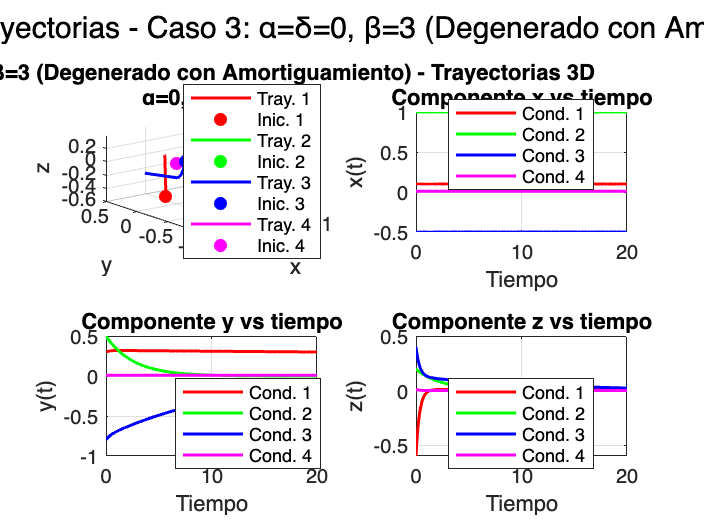


alpha_val = 0;
beta_val = 3;
delta_val = 0;
case_name = 'Caso 3: α=δ=0, β=3 (Degenerado con Amortiguamiento)';
t_span = [0, 20];

% Definir el sistema de ecuaciones
lorenz_system = @(t, X) [
    alpha_val * (X(2) - X(1));
    -X(1)*X(3) + delta_val * X(2);
    X(1)*X(2) - beta_val * X(3)
];

figure('Position', [100, 100, 1200, 900]);

for i = 1:size(initial_conditions_set, 1)
    try
        % Resolver el sistema
        [t, X] = ode45(lorenz_system, t_span, initial_conditions_set(i, :));
        
        % Gráfica 3D
        subplot(2, 2, 1);
        plot3(X(:,1), X(:,2), X(:,3), colors(i), 'LineWidth', 1.5);
        hold on;
        plot3(X(1,1), X(1,2), X(1,3), [colors(i) 'o'], 'MarkerSize', 6, 'MarkerFaceColor', colors(i));
        
        % Gráficas de componentes vs tiempo
        subplot(2, 2, 2);
        plot(t, X(:,1), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 3);
        plot(t, X(:,2), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 4);
        plot(t, X(:,3), colors(i), 'LineWidth', 1.5); hold on;
    catch ME
        fprintf('Advertencia: No se pudo resolver para condición inicial %d\n', i);
    end
end

% Configurar gráfica 3D
subplot(2, 2, 1);
grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title(sprintf('%s - Trayectorias 3D\nα=%g, β=%g, δ=%g', case_name, alpha_val, beta_val, delta_val));
legend('Tray. 1', 'Inic. 1', 'Tray. 2', 'Inic. 2', 'Tray. 3', 'Inic. 3', 'Tray. 4', 'Inic. 4', 'Location', 'best');

% Configurar gráficas de componentes
subplot(2, 2, 2);
grid on; xlabel('Tiempo'); ylabel('x(t)');
title('Componente x vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 3);
grid on; xlabel('Tiempo'); ylabel('y(t)');
title('Componente y vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 4);
grid on; xlabel('Tiempo'); ylabel('z(t)');
title('Componente z vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

sgtitle(sprintf('Análisis de Trayectorias - %s', case_name));


%% CASO 4: α=0, δ≠0, β≠0 (Inestable)
fprintf('\nGraficando CASO 4 (α=0, δ=20, β=3)...\n');


Graficando CASO 4 (α=0, δ=20, β=3)...


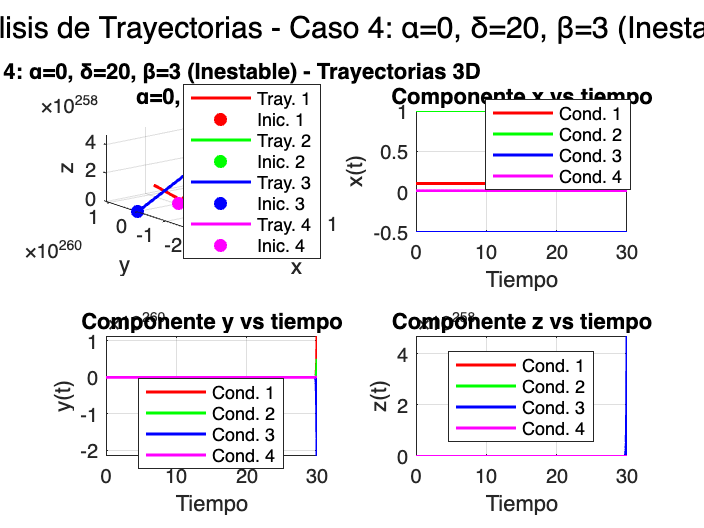


alpha_val = 0;
beta_val = 3;
delta_val = 20;
case_name = 'Caso 4: α=0, δ=20, β=3 (Inestable)';
t_span = [0, 30];

% Definir el sistema de ecuaciones
lorenz_system = @(t, X) [
    alpha_val * (X(2) - X(1));
    -X(1)*X(3) + delta_val * X(2);
    X(1)*X(2) - beta_val * X(3)
];

figure('Position', [100, 100, 1200, 900]);

for i = 1:size(initial_conditions_set, 1)
    try
        % Resolver el sistema
        [t, X] = ode45(lorenz_system, t_span, initial_conditions_set(i, :));
        
        % Gráfica 3D
        subplot(2, 2, 1);
        plot3(X(:,1), X(:,2), X(:,3), colors(i), 'LineWidth', 1.5);
        hold on;
        plot3(X(1,1), X(1,2), X(1,3), [colors(i) 'o'], 'MarkerSize', 6, 'MarkerFaceColor', colors(i));
        
        % Gráficas de componentes vs tiempo
        subplot(2, 2, 2);
        plot(t, X(:,1), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 3);
        plot(t, X(:,2), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 4);
        plot(t, X(:,3), colors(i), 'LineWidth', 1.5); hold on;
    catch ME
        fprintf('Advertencia: No se pudo resolver para condición inicial %d\n', i);
    end
end

% Configurar gráfica 3D
subplot(2, 2, 1);
grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title(sprintf('%s - Trayectorias 3D\nα=%g, β=%g, δ=%g', case_name, alpha_val, beta_val, delta_val));
legend('Tray. 1', 'Inic. 1', 'Tray. 2', 'Inic. 2', 'Tray. 3', 'Inic. 3', 'Tray. 4', 'Inic. 4', 'Location', 'best');

% Configurar gráficas de componentes
subplot(2, 2, 2);
grid on; xlabel('Tiempo'); ylabel('x(t)');
title('Componente x vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 3);
grid on; xlabel('Tiempo'); ylabel('y(t)');
title('Componente y vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 4);
grid on; xlabel('Tiempo'); ylabel('z(t)');
title('Componente z vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

sgtitle(sprintf('Análisis de Trayectorias - %s', case_name));


%% CASO 5: α≠0, β=0, δ≠0 (Singular)
fprintf('\nGraficando CASO 5 (α=36, β=0, δ=20)...\n');


Graficando CASO 5 (α=36, β=0, δ=20)...


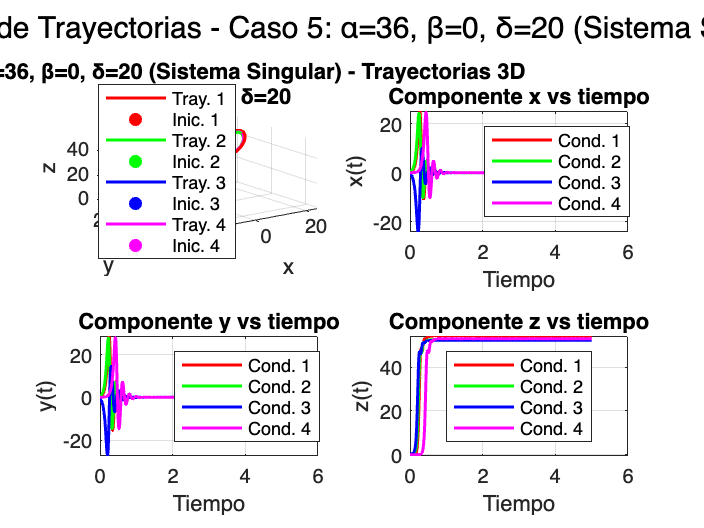


alpha_val = 36;
beta_val = 0;
delta_val = 20;
case_name = 'Caso 5: α=36, β=0, δ=20 (Sistema Singular)';
t_span = [0, 5];

% Definir el sistema de ecuaciones
lorenz_system = @(t, X) [
    alpha_val * (X(2) - X(1));
    -X(1)*X(3) + delta_val * X(2);
    X(1)*X(2) - beta_val * X(3)
];

figure('Position', [100, 100, 1200, 900]);

for i = 1:size(initial_conditions_set, 1)
    try
        % Resolver el sistema
        [t, X] = ode45(lorenz_system, t_span, initial_conditions_set(i, :));
        
        % Gráfica 3D
        subplot(2, 2, 1);
        plot3(X(:,1), X(:,2), X(:,3), colors(i), 'LineWidth', 1.5);
        hold on;
        plot3(X(1,1), X(1,2), X(1,3), [colors(i) 'o'], 'MarkerSize', 6, 'MarkerFaceColor', colors(i));
        
        % Gráficas de componentes vs tiempo
        subplot(2, 2, 2);
        plot(t, X(:,1), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 3);
        plot(t, X(:,2), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 4);
        plot(t, X(:,3), colors(i), 'LineWidth', 1.5); hold on;
    catch ME
        fprintf('Advertencia: No se pudo resolver para condición inicial %d\n', i);
    end
end

% Configurar gráfica 3D
subplot(2, 2, 1);
grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title(sprintf('%s - Trayectorias 3D\nα=%g, β=%g, δ=%g', case_name, alpha_val, beta_val, delta_val));
legend('Tray. 1', 'Inic. 1', 'Tray. 2', 'Inic. 2', 'Tray. 3', 'Inic. 3', 'Tray. 4', 'Inic. 4', 'Location', 'best');

% Configurar gráficas de componentes
subplot(2, 2, 2);
grid on; xlabel('Tiempo'); ylabel('x(t)');
title('Componente x vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 3);
grid on; xlabel('Tiempo'); ylabel('y(t)');
title('Componente y vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 4);
grid on; xlabel('Tiempo'); ylabel('z(t)');
title('Componente z vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

sgtitle(sprintf('Análisis de Trayectorias - %s', case_name));



%% CASO 6: α≠0, β≠0,  (Singular)
fprintf('\nGraficando CASO 6 (α=36, β=3, δ=20)...\n');


Graficando CASO 6 (α=36, β=3, δ=20)...


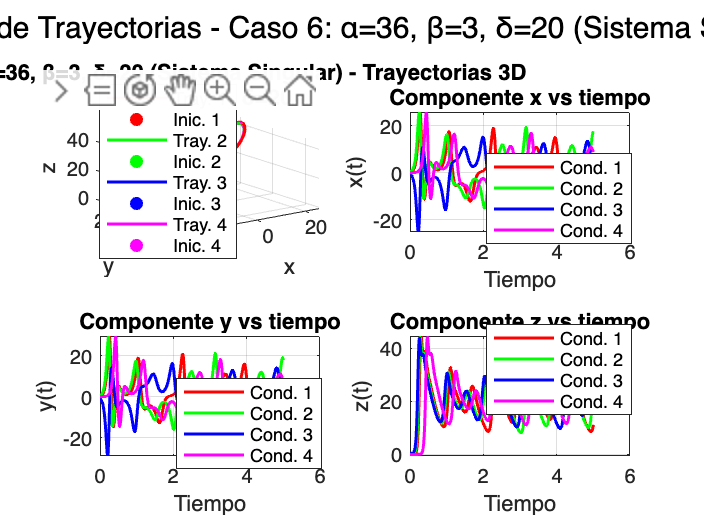


alpha_val = 36;
beta_val = 3;
delta_val = 20;
case_name = 'Caso 6: α=36, β=3, δ=20 (Sistema Singular)';
t_span = [0, 5];

% Definir el sistema de ecuaciones
lorenz_system = @(t, X) [
    alpha_val * (X(2) - X(1));
    -X(1)*X(3) + delta_val * X(2);
    X(1)*X(2) - beta_val * X(3)
];

figure('Position', [100, 100, 1200, 900]);

for i = 1:size(initial_conditions_set, 1)
    try
        % Resolver el sistema
        [t, X] = ode45(lorenz_system, t_span, initial_conditions_set(i, :));
        
        % Gráfica 3D
        subplot(2, 2, 1);
        plot3(X(:,1), X(:,2), X(:,3), colors(i), 'LineWidth', 1.5);
        hold on;
        plot3(X(1,1), X(1,2), X(1,3), [colors(i) 'o'], 'MarkerSize', 6, 'MarkerFaceColor', colors(i));
        
        % Gráficas de componentes vs tiempo
        subplot(2, 2, 2);
        plot(t, X(:,1), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 3);
        plot(t, X(:,2), colors(i), 'LineWidth', 1.5); hold on;
        
        subplot(2, 2, 4);
        plot(t, X(:,3), colors(i), 'LineWidth', 1.5); hold on;
    catch ME
        fprintf('Advertencia: No se pudo resolver para condición inicial %d\n', i);
    end
end

% Configurar gráfica 3D
subplot(2, 2, 1);
grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title(sprintf('%s - Trayectorias 3D\nα=%g, β=%g, δ=%g', case_name, alpha_val, beta_val, delta_val));
legend('Tray. 1', 'Inic. 1', 'Tray. 2', 'Inic. 2', 'Tray. 3', 'Inic. 3', 'Tray. 4', 'Inic. 4', 'Location', 'best');

% Configurar gráficas de componentes
subplot(2, 2, 2);
grid on; xlabel('Tiempo'); ylabel('x(t)');
title('Componente x vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 3);
grid on; xlabel('Tiempo'); ylabel('y(t)');
title('Componente y vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

subplot(2, 2, 4);
grid on; xlabel('Tiempo'); ylabel('z(t)');
title('Componente z vs tiempo');
legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');

sgtitle(sprintf('Análisis de Trayectorias - %s', case_name));



%% ANÁLISIS DETALLADO DE COMPORTAMIENTO DEGENERADO
fprintf('\n=== ANÁLISIS DETALLADO DE COMPORTAMIENTO DEGENERADO ===\n');


=== ANÁLISIS DETALLADO DE COMPORTAMIENTO DEGENERADO ===



% Análisis del Caso 2: α=β=δ=0
fprintf('\n1. CASO 2 (α=β=δ=0):\n');


1. CASO 2 (α=β=δ=0):


fprintf('   Sistema: x''=0, y''=-xz, z''=xy\n');

   Sistema: x'=0, y'=-xz, z'=xy


fprintf('   - x(t) = x₀ (constante)\n');

   - x(t) = x₀ (constante)


fprintf('   - Si x₀ = 0: y''=0, z''=0 → todo punto es equilibrio\n');

   - Si x₀ = 0: y'=0, z'=0 → todo punto es equilibrio


fprintf('   - Si x₀ ≠ 0: Sistema se reduce a y''=-x₀z, z''=x₀y\n');

   - Si x₀ ≠ 0: Sistema se reduce a y'=-x₀z, z'=x₀y


fprintf('   - Solución: y(t) = A*cos(x₀*t) + B*sin(x₀*t)\n');

   - Solución: y(t) = A*cos(x₀*t) + B*sin(x₀*t)


fprintf('   - Comportamiento oscilatorio armónico\n');

   - Comportamiento oscilatorio armónico



% Análisis del Caso 3: α=δ=0, β≠0
fprintf('\n2. CASO 3 (α=δ=0, β≠0):\n');


2. CASO 3 (α=δ=0, β≠0):


fprintf('   Sistema: x''=0, y''=-xz, z''=xy - βz\n');

   Sistema: x'=0, y'=-xz, z'=xy - βz


fprintf('   - x(t) = x₀ (constante)\n');

   - x(t) = x₀ (constante)


fprintf('   - Si x₀ = 0: y''=0, z''=-βz → z decae exponencialmente\n');

   - Si x₀ = 0: y'=0, z'=-βz → z decae exponencialmente


fprintf('   - Si x₀ ≠ 0: Sistema lineal en (y,z) con matriz:\n');

   - Si x₀ ≠ 0: Sistema lineal en (y,z) con matriz:


fprintf('        [0   -x₀]\n');

        [0   -x₀]


fprintf('        [x₀  -β]\n');

        [x₀  -β]



% Análisis del Caso 4: α=0, δ≠0
fprintf('\n3. CASO 4 (α=0, δ≠0):\n');


3. CASO 4 (α=0, δ≠0):


fprintf('   Sistema: x''=0, y''=-xz + δy, z''=xy - βz\n');

   Sistema: x'=0, y'=-xz + δy, z'=xy - βz


fprintf('   - x(t) = x₀ (constante)\n');

   - x(t) = x₀ (constante)


fprintf('   - Si x₀ = 0: y''=δy (crecimiento exponencial), z''=-βz\n');

   - Si x₀ = 0: y'=δy (crecimiento exponencial), z'=-βz


fprintf('   - Si x₀ ≠ 0: Sistema no lineal con crecimiento potencial\n');

   - Si x₀ ≠ 0: Sistema no lineal con crecimiento potencial



% Análisis del Caso 5: α≠0, β=0, δ≠0
fprintf('\n4. CASO 5 (α≠0, β=0, δ≠0):\n');


4. CASO 5 (α≠0, β=0, δ≠0):


fprintf('   Sistema: x''=α(y-x), y''=-xz + δy, z''=xy\n');

   Sistema: x'=α(y-x), y'=-xz + δy, z'=xy


fprintf('   - Sin término de disipación en z (β=0)\n');

   - Sin término de disipación en z (β=0)


fprintf('   - z puede crecer sin límite si xy > 0\n');

   - z puede crecer sin límite si xy > 0


fprintf('   - Comportamiento típicamente explosivo\n');

   - Comportamiento típicamente explosivo



%% RESUMEN FINAL
fprintf('\n=== RESUMEN FINAL CORREGIDO ===\n');


=== RESUMEN FINAL CORREGIDO ===


fprintf('Caso 1 (α≠0, β≠0, δ≠0): INESTABLE (atractor caótico)\n');

Caso 1 (α≠0, β≠0, δ≠0): INESTABLE (atractor caótico)


fprintf('Caso 2 (α=β=δ=0): SISTEMA DEGENERADO - Oscilaciones armónicas\n');

Caso 2 (α=β=δ=0): SISTEMA DEGENERADO - Oscilaciones armónicas


fprintf('Caso 3 (α=δ=0, β≠0): SISTEMA DEGENERADO - Comportamiento dependiente de x₀\n');

Caso 3 (α=δ=0, β≠0): SISTEMA DEGENERADO - Comportamiento dependiente de x₀


fprintf('Caso 4 (α=0, δ≠0): INESTABLE para δ>0\n');

Caso 4 (α=0, δ≠0): INESTABLE para δ>0


fprintf('Caso 5 (α≠0, β=0): SISTEMA SINGULAR - Crecimiento potencial\n');

Caso 5 (α≠0, β=0): SISTEMA SINGULAR - Crecimiento potencial


fprintf('Caso 6 (α≠0, β≠0): INESTABLE para parámetros típicos\n');

Caso 6 (α≠0, β≠0): INESTABLE para parámetros típicos



fprintf('\n=== CONCLUSIONES ===\n');


=== CONCLUSIONES ===


fprintf('1. El análisis lineal falla para sistemas degenerados\n');

1. El análisis lineal falla para sistemas degenerados


fprintf('2. La dinámica real se revela mediante simulación numérica\n');

2. La dinámica real se revela mediante simulación numérica


fprintf('3. Los casos degenerados muestran alta sensibilidad a condiciones iniciales\n');

3. Los casos degenerados muestran alta sensibilidad a condiciones iniciales


fprintf('4. El comportamiento puede ser cualitativamente diferente al predicho por linealización\n');

4. El comportamiento puede ser cualitativamente diferente al predicho por linealización
